# 4(b) 双线性Z变换法设计Chebyshev数字滤波器

## （1）Chebyshev数字高通滤波器：

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;

fp=300;fs=200;
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=30;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 2.7528e+03

was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


%bw=wap(2)-wap(1)
%w0=sqrt(wap(1)*wap(2))
[bt,at]=lp2hp(b,a,wap)

bt =     0.7079   -0.0000   -0.0000   -0.0000   -0.0269


at = 	1.0e+14 *

    0.0000    0.0000    0.0000    0.0007    3.2444


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 =     0.0156   -0.0622    0.0933   -0.0622    0.0156


az1 =     1.0000    1.9327    2.2554    1.4562    0.4851


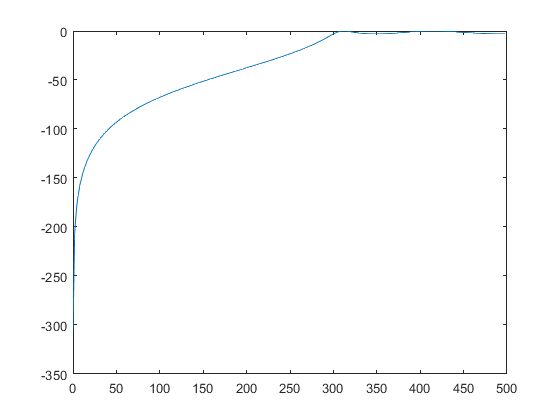

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))

## （2）Chebyshev数字低通滤波器：

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;

fp=200;fs=300;
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=30;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 1.4531e+03

was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


%bw=wap(2)-wap(1)
%w0=sqrt(wap(1)*wap(2))
[bt,at]=lp2lp(b,a,wap)

bt = 5.5861e+11

at = 	1.0e+11 *

    0.0000    0.0000    0.0000    0.0124    7.8905


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 =     0.0156    0.0622    0.0933    0.0622    0.0156


az1 =     1.0000   -1.9327    2.2554   -1.4562    0.4851


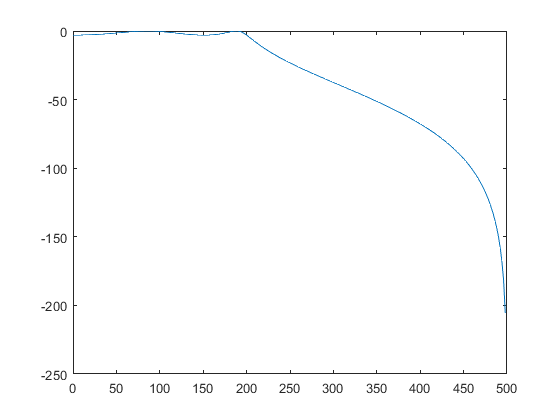

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))

## （3）Chebyshev数字带通滤波器：

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;


fp=[270 330];fs=[200 400];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=50;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 	1.0e+03 *

    2.2686    3.3818


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


bw=wap(2)-wap(1)

bw = 1.1133e+03

w0=sqrt(wap(1)*wap(2))

w0 = 2.7698e+03

[bt,at]=lp2bp(b,a,w0,bw)

bt = 	1.0e+11 *

    1.9245    0.0000   -0.0000   -0.0000   -0.0013


at = 	1.0e+27 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    3.4641


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 = 	1.0e+-3 *

    0.1435    0.0000   -0.5738    0.0000    0.8608    0.0000   -0.5738    0.0000    0.1435


az1 =     1.0000    2.4050    5.8270    7.5438    9.3294    7.1430    5.2252    2.0398    0.8033


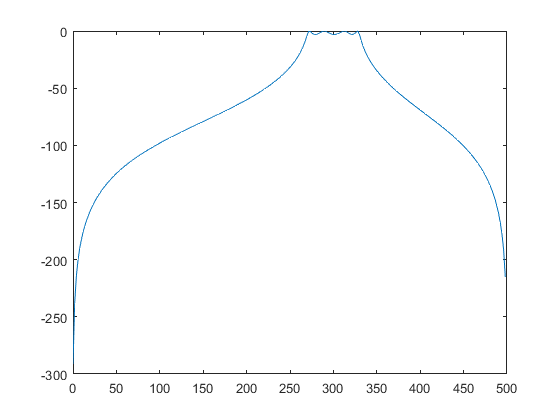

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))

## （4）Chebyshev数字带阻滤波器：

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;


fp=[200 400];fs=[270 330];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=50;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 	1.0e+03 *

    1.4531    6.1554


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


bw=wap(2)-wap(1)

bw = 4.7023e+03

w0=sqrt(wap(1)*wap(2))

w0 = 2.9907e+03

[bt,at]=lp2bs(b,a,w0,bw)

bt = 	1.0e+27 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    4.5309


at = 	1.0e+27 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0077    6.4000


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 =     0.0788    0.2408    0.5912    0.8630    1.0516    0.8630    0.5912    0.2408    0.0788


az1 =     1.0000    1.4643    0.7738    0.8108    1.3076    0.4411   -0.0526    0.4021    0.3495


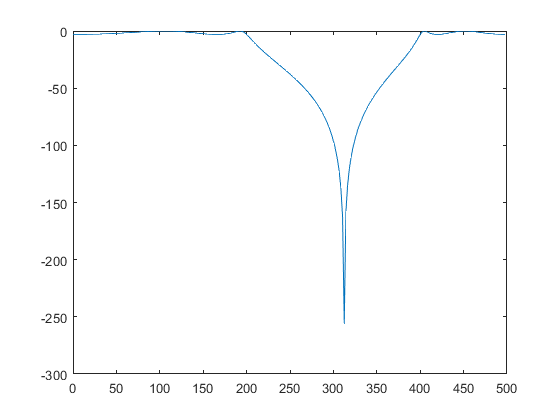

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))